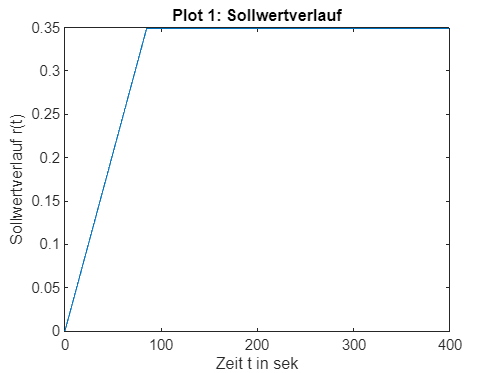

clear



% Sollwertverlauf r(t)
t = 0:0.01:400; % von 0-400 in 0.01 schritten

i = 1;
while i <= 40001

    if i <= 8501
    r(i) = (i-1).*0.01.*(deg2rad(20)./85);
    
    elseif 8501 < i & i <= 40001
    r(i) = deg2rad(20);
    end

    i = i+1;
end

plot(t,r);
title('Plot 1: Sollwertverlauf');
xlabel('Zeit t in sek');
ylabel('Sollwertverlauf r(t)');




% Traegheitsmoment J
J = 800 % kgm^2

J = 800


s = tf('s');

% Regelkreis:
G = 1/(J.*s^2);

% Regler:
%Startwerte:
omega = 0.2;
zeta = 0.85;
K = (s*0.1*omega^2 + s*0.1*J + s*2*zeta*omega*J+omega^2 +J)/(0.1*s +1);

T = (G*K)/(1 + G*K); % hier mit feedback arbeiten
S = 1/(1 + G*K); % hier mit feedback arbeiten
GS = G*S; % hier mit minreal arbeiten
KS = K*S; % hier mit minreal arbeiten

% minreal kuerz pole und nst der multiplizierten Uebertragungsfunktionen

T1 = feedback(G*K,1); % sys1: G*K, sys2: 1
S1 = feedback(1,G*K); % sys1: 1, sys2: G*K
GS1 = minreal(G*S); 
KS1 = minreal(K*S);

